20180406

EE627

clear;
close all;
clc;

HW5

Define your own Matlab function for matrix factorization. 

`matrix_factorization(R,P,Q,K, steps, alpha, beta)`

Use the sample code I provide to test if your function works or not. 

% %{
R=[ 5 3 0 1;
    4 0 0 1;
    1 1 0 5;
    1 0 0 4;
    0 1 5 4];
[nRow, nCol]=size(R);
K=2;
P=rand(nRow, K);
Q=rand(K, nCol);

steps=5000;
alpha=0.0002;
beta=0.02;

R(R==0)=NaN;
[nP, nQ]=matrix_factorization(R,P,Q,K, steps, alpha, beta);
[nP*nQ]

ans =     5.0234    2.8585    5.0700    0.9973
    3.9421    2.2477    4.1324    0.9962
    1.1006    0.7263    4.5255    4.9617
    0.9465    0.6185    3.6804    3.9732
    2.2726    1.3688    4.8752    4.0371


[R]

R =      5     3   NaN     1
     4   NaN   NaN     1
     1     1   NaN     5
     1   NaN   NaN     4
   NaN     1     5     4



R=[ 4 3 0 1 2;
    5 0 0 1 0;
    1 2 1 5 4;
    1 0 0 4 0;
    0 1 5 4 0;
    5 5 0 0 1];
[nRow, nCol]=size(R);
K=3;
P=rand(nRow, K);
Q=rand(K, nCol);

steps=10000;
alpha=0.0002;
beta=0.02;

R(R==0)=NaN;
[nP, nQ]=matrix_factorization(R,P,Q,K, steps, alpha, beta);
[nP*nQ]
[R]


reference

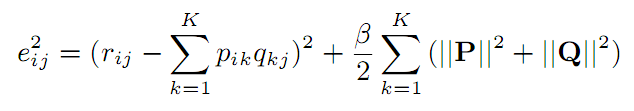

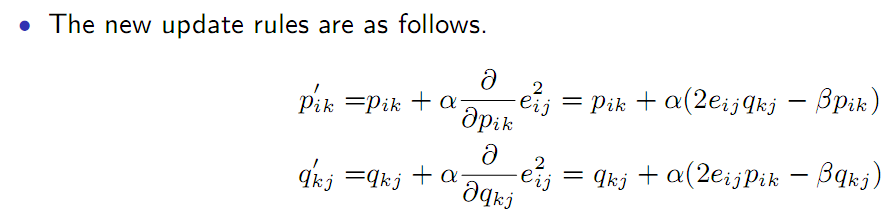

wiki Non-negative_matrix_factorization

V=WH

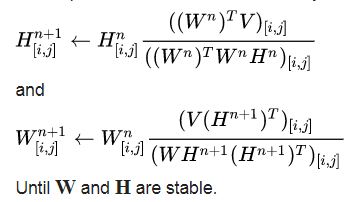

function [nP, nQ]=matrix_factorization(R,P,Q,K,steps,alpha,beta)
[m,n] = size(R);
%     R(R==0)=NaN;
% steps1 = steps;
nP = P;
nQ = Q;
while steps>0
    e = R-P*Q;
    for i = 1:m
        for j = 1:n
            if isnan(R(i,j))
                continue
            end
            nP(i,:) = P(i,:)+alpha*(2*e(i,j)*Q(:,j).'-beta*P(i,:));
            nQ(:,j) = Q(:,j)+alpha*(2*e(i,j)*P(i,:).'-beta*Q(:,j));
            P = nP;
            Q = nQ;
        end
    end
    steps = steps-1;
%     e1(:,:,steps1+1-steps) = e;
%     steps = steps-1;
end
% plot(reshape(e1(1,1,:),[1,steps1]));
% hold on;
% plot(reshape(e1(1,2,:),[1,steps1]));
% hold off;
end






%}






